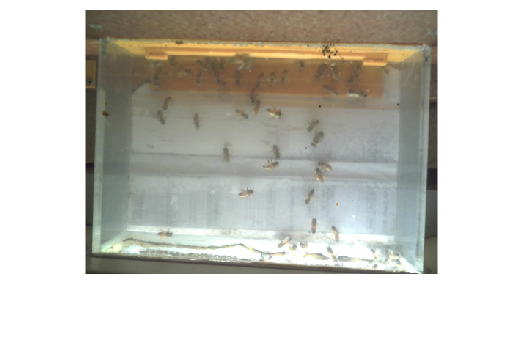

sample_image=imread('bee2022-09-20-115721.jpg');
sample_image=imresize(sample_image,0.3);
%1600by1200 image to 480by360
%whos sample_image
imshow(sample_image)

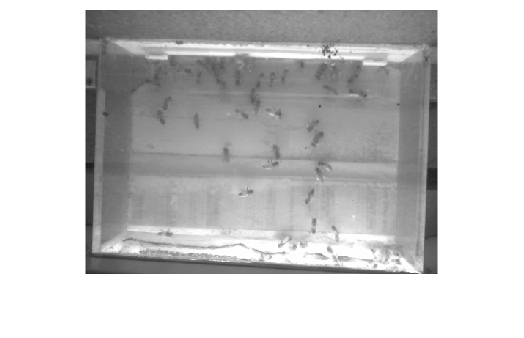

%gray_image=rgb2gray(sample_image);

imshow(sample_image(:,:,1));

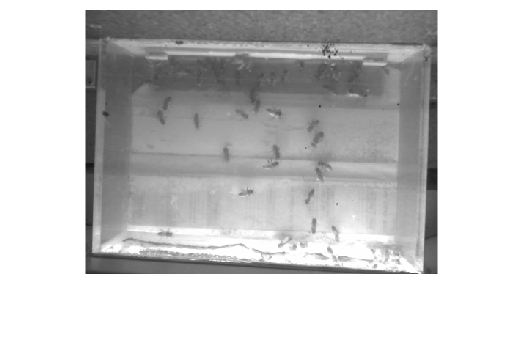

imshow(sample_image(:,:,2));

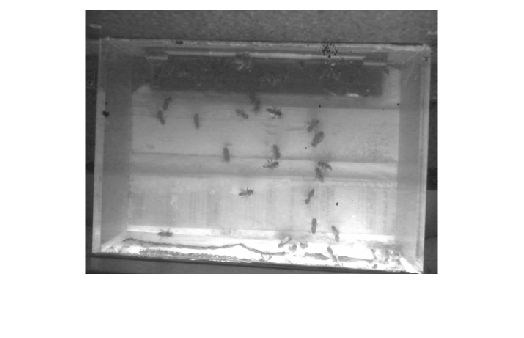

imshow(sample_image(:,:,3));

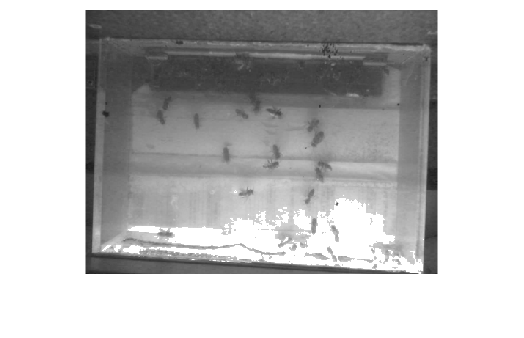


blue_image=sample_image(:,:,3);
blue_image(blue_image>210)=255;
imshow(blue_image);


% gray_image=sample_image(:,:,1)*1 ...
%            +sample_image(:,:,2)*0 ...
%            +sample_image(:,:,3)*0;
% 
% imshow(gray_image)

% BW=edge(gray_image,"Canny");
% imshow(BW);

%checkingFamilyImage=checkingFamily(gray_image);

%val_uint8=checkingFamilyImage/max(max(checkingFamilyImage));
%val_uint8(gray_image>180)=1;

%imshow(val_uint8);



function res=checkingFamily(image)
    %res=uint8(zeros(1200,1600));
    res=(zeros(360,480));
    res(1,1)=1;
    num=2;
    for i=1:360
        if i~=1
            check=check_pixel(image(i-1:i,1));
            if check
                res(i,1)=res(i-1,1);
            else
                res(i,1)=num;
                num=num+1;
            end
        end

        for j=2:480
            check=check_pixel(image(i,j-1:j));
            if check
                res(i,j)=res(i,j-1);
            else
                res(i,j)=num;
                num=num+1;
            end

            if i~=1
                if image(i,j)==image(i-1,j)
                    temp=res(i,j);
                    res(i,j)=res(i-1,j);
                    for k=j-1:-1:1
                        if temp~=res(i,k)
                            break;
                        end
                        res(i,k)=temp;
                    end
                end
            end
        end
    end
end

function val=check_pixel(input_vector)
    val=0;
    if abs(input_vector(1)-input_vector(2))<1
        val=1;
    end
end